# Create MATLAB Environment Using Custom Functions

This example shows how to create a cart-pole environment by supplying custom dynamic functions in MATLAB®.

Using the `rlFunctionEnv` function, you can create a MATLAB reinforcement learning environment from an observation specification, an action specification, and user-defined `step` and `reset` functions. You can then train a reinforcement learning agent in this environment. The necessary `step` and `reset` functions are already defined for this example.

Creating an environment using custom functions is useful for environments with less complex dynamics, environments with no special visualization requirements, or environments with interfaces to third-party libraries. For more complex environments, you can create an environment object using a template class. For more information, see [Create Custom MATLAB Environment from Template](docid:rl_ug#mw_fb822f88-ff27-49e4-b9f2-9e81b1175a89).

For more information on creating reinforcement learning environments, see [Create MATLAB Environments for Reinforcement Learning](docid:rl_ug#mw_7a0b131e-4d8e-4af1-ba35-9c55bc006f48) and [Create Simulink Environments for Reinforcement Learning](docid:rl_ug#mw_0e8060ca-2e7a-4d41-90d1-3bf4aeb76099).

## Cart-Pole MATLAB Environment

The cart-pole environment is a pole attached to an unactuated joint on a cart, which moves along a frictionless track. The training goal is to make the pendulum stand upright without falling over.

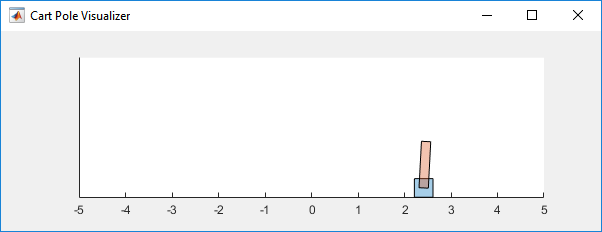

For this environment:

- The upward balanced pendulum position is `0` radians, and the downward hanging position is `pi` radians.

- The pendulum starts upright with an initial angle that is between –0.5 and 0.05.

- The force action signal from the agent to the environment is from –10 to 10 N.

- The observations from the environment are the cart position, cart velocity, pendulum angle, and pendulum angle derivative.

- The episode terminates if the pole is more than 12 degrees from vertical, or if the cart moves more than 2.4 m from the original position.

- A reward of +1 is provided for every time step that the pole remains upright. A penalty of –10 is applied when the pendulum falls.

For more information on this model, see [Load Predefined Control System Environments](docid:rl_ug#mw_537f0c6d-2ccd-454b-95fa-3ee88ece74aa).

## Observation and Action Specifications

The observations from the environment are the cart position, cart velocity, pendulum angle, and pendulum angle derivative.

ObservationInfo = rlNumericSpec([4 1]);
ObservationInfo.Name = 'CartPole States';
ObservationInfo.Description = 'x, dx, theta, dtheta';

The environment has a discrete action space where the agent can apply one of two possible force values to the cart: `-10` or `10` N.

ActionInfo = rlFiniteSetSpec([-10 10]);
% ActionInfo = rlNumericSpec([1 1], ...
% 	'LowerLimit',-ones(1,1)*10, ...
% 	'UpperLimit',ones(1,1)*10);
ActionInfo.Name = 'CartPole Action';

For more information on specifying environment actions and observations, see [`rlNumericSpec`](docid:rl_ref#mw_1a66fdf2-e758-4985-a541-61943fb15e79) and [`rlFiniteSetSpec`](docid:rl_ref#mw_68f70adf-d6a9-4cbe-846c-a7d0823c0774).

## Create Environment Using Function Names

To define a custom environment, first specify the custom `step` and `reset` functions. These functions must be in your current working folder or on the MATLAB path.

The custom `reset` function sets the default state of the environment. This function must have the following signature.

To pass information from one step to the next, such as the environment state, use `LoggedSignals`. For this example, `LoggedSignals` contains the states of the cart-pole environment: the position and velocity of the cart, the pendulum angle, and the pendulum angle derivative. The `reset` function sets the cart angle to a random value each time the environment is reset.

For this example, use the custom reset function defined in `myResetFunction.m`.

type myResetFunction.m

function [InitialObservation, LoggedSignal] = myResetFunction()
% Reset function to place custom cart-pole environment into a random
% initial state.

% Theta (randomize)
T0 = 2 * 0.05 * rand() - 0.05;
% Thetadot
Td0 = 0;
% X
X0 = 0;
% Xdot
Xd0 = 0;

% Return initial environment state variables as logged signals.
LoggedSignal.State = [X0;Xd0;T0;Td0];
InitialObservation = LoggedSignal.State;

end



The custom `step` function specifies how the environment advances to the next state based on a given action. This function must have the following signature.

To get the new state, the environment applies the dynamic equation to the current state stored in `LoggedSignals`, which is similar to giving an initial condition to a differential equation. The new state is stored in `LoggedSignals` and returned as an output.

For this example, use the custom step function defined in `myStepFunction.m`. For implementation simplicity, this function redefines physical constants, such as the cart mass, every time `step` is executed.

type myStepFunction.m

function [NextObs,Reward,IsDone,LoggedSignals] = myStepFunction(Action,LoggedSignals)
% Custom step function to construct cart-pole environment for the function
% name case.
%
% This function applies the given action to the environment and evaluates
% the system dynamics for one simulation step.

% Define the environment constants.

% Acceleration due to gravity in m/s^2
Gravity = 9.8;
% Mass of the cart
CartMass = 1.0;
% Mass of the pole
PoleMass = 0.1;
% Half the length of the pole
HalfPoleLength = 0.5;
% Max force the input can apply
MaxForce = 10;
% Sample time
Ts = 0.02;
% Pole angle at which to fail the episode
AngleThreshold = 12 * pi/180;
% Cart distance at which to fail the episode
DisplacementThreshold = 2.4;
% Reward each time step the cart-pole is balanced
RewardForNotFalling = 1;
% Penalty when the cart-pole fails to balance
PenaltyForFalling = -10;

% Check if the given action is valid.
if ~ismember(Action,[-MaxForce MaxForce])
    error('Action must be %g for going left 

Construct the custom environment using the defined observation specification, action specification, and function names.

env = rlFunctionEnv(ObservationInfo,ActionInfo,'myStepFunction','myResetFunction');

To verify the operation of your environment, `rlFunctionEnv` automatically calls `validateEnvironment` after creating the environment.

## Create Environment Using Function Handles

You can also define custom functions that have additional input arguments beyond the minimum required set. For example, to pass the additional arguments `arg1` and `arg2` to both the step and rest function, use the following code.

To use these functions with `rlFunctionEnv`, you must use anonymous function handles.

For more information, see [Anonymous Functions](docid:matlab_prog#f4-70115).

Using additional input arguments can create a more efficient environment implementation. For example, `myStepFunction2.m` contains a custom `step` function that takes the environment constants as an input argument (`envConstants`). By doing so, this function avoids redefining the environment constants at each step.

type myStepFunction2.m

function [NextObs,Reward,IsDone,LoggedSignals] = myStepFunction2(Action,LoggedSignals,EnvConstants)
% Custom step function to construct cart-pole environment for the function
% handle case.
%
% This function applies the given action to the environment and evaluates
% the system dynamics for one simulation step.

% Check if the given action is valid.
if ~ismember(Action,[-EnvConstants.MaxForce EnvConstants.MaxForce])
    error('Action must be %g for going left and %g for going right.',...
        -EnvConstants.MaxForce,EnvConstants.MaxForce);
end
Force = Action;

% Unpack the state vector from the logged signals.
State = LoggedSignals.State;
XDot = State(2);
Theta = State(3);
ThetaDot = State(4);

% Cache to avoid recomputation.
CosTheta = cos(Theta);
SinTheta = sin(Theta);
SystemMass = EnvConstants.MassCart + EnvConstants.MassPole;
temp = (Force + EnvConstants.MassPole*EnvConstants.Length*ThetaDot*ThetaDot*SinTheta)/SystemMass;

% Apply motion equations.
ThetaDotDot = (EnvConstants.Gra

Create the structure that contains the environment constants.

% Acceleration due to gravity in m/s^2
envConstants.Gravity = 9.8;
% Mass of the cart
envConstants.MassCart = 1.0;
% Mass of the pole
envConstants.MassPole = 0.1;
% Half the length of the pole
envConstants.Length = 0.5;
% Max force the input can apply
envConstants.MaxForce = 10;
% Sample time
envConstants.Ts = 0.02;
% Angle at which to fail the episode
envConstants.ThetaThresholdRadians = 12 * pi/180;
% Distance at which to fail the episode
envConstants.XThreshold = 2.4;
% Reward each time step the cart-pole is balanced
envConstants.RewardForNotFalling = 1;
% Penalty when the cart-pole fails to balance
envConstants.PenaltyForFalling = -5;

Create an anonymous function handle to the custom `step` function, passing `envConstants` as an additional input argument. Because `envConstants` is available at the time that `StepHandle` is created, the function handle includes those values. The values persist within the function handle even if you clear the variables.

StepHandle = @(Action,LoggedSignals) myStepFunction2(Action,LoggedSignals,envConstants);

Use the same `reset` function, specifying it as a function handle rather than by using its name.

ResetHandle = @myResetFunction;

Create the environment using the custom function handles.

env2 = rlFunctionEnv(ObservationInfo,ActionInfo,StepHandle,ResetHandle);

## Validate Custom Functions

Before you train an agent in your environment, the best practice is to validate the behavior of your custom functions. To do so, you can initialize your environment using the `reset` function and run one simulation step using the `step` function. For reproducibility, set the random generator seed before validation.

Validate the environment created using function names.

rng(0);
InitialObs = reset(env)

InitialObs =          0
         0
    0.0315
         0


[NextObs,Reward,IsDone,LoggedSignals] = step(env,10);
NextObs

NextObs =          0
    0.1947
    0.0315
   -0.2826


Validate the environment created using function handles.

rng(0);
InitialObs2 = reset(env2)

InitialObs2 =          0
         0
    0.0315
         0


[NextObs2,Reward2,IsDone2,LoggedSignals2] = step(env2,10);
NextObs

NextObs =          0
    0.1947
    0.0315
   -0.2826


Both environments initialize and simulate successfully, producing the same state values in `NextObs`.

*Copyright 2019 The MathWorks, Inc.*